k = 1

ans = 187.9057

ans = -331.3884

f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '3New.png'

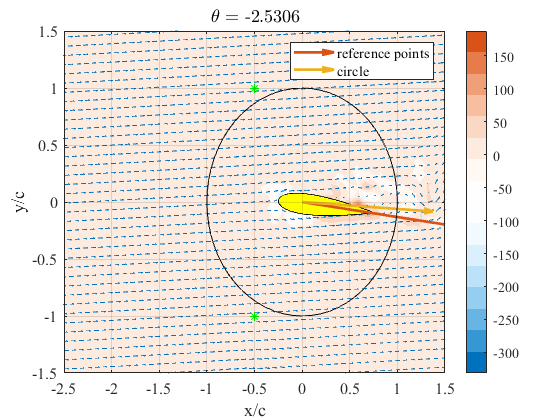

k = 16

ans = 38.9640

ans = -28.9224

f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '87New.png'

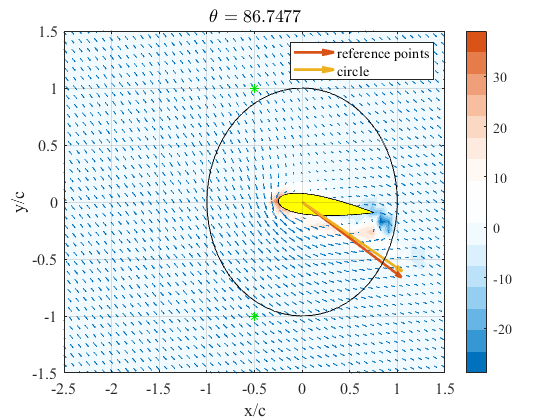

k = 22

ans = 46.9702

ans = -31.8191

f =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '122New.png'

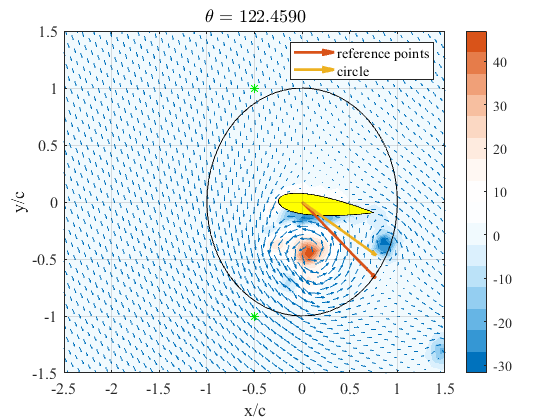

k = 25

ans = 43.6460

ans = -31.9731

f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '140New.png'

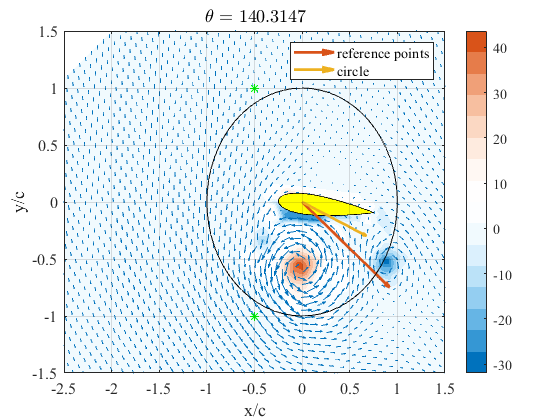

k = 27

ans = 36.9193

ans = -32.9111

f =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '152New.png'

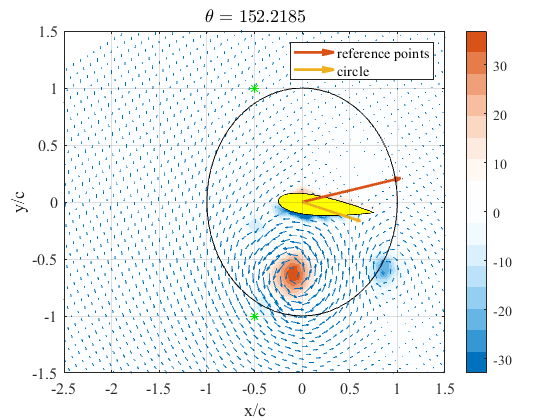

k = 32

ans = 384.8908

ans = -201.9894

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '182New.png'

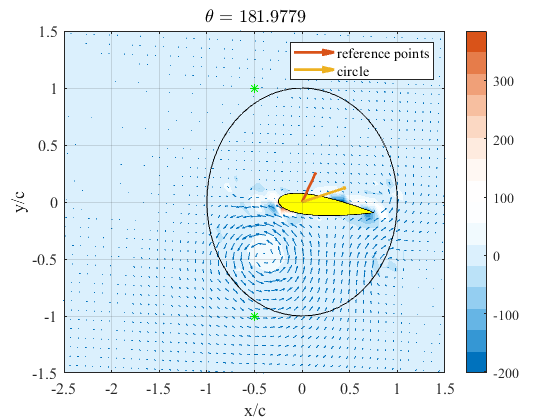

k = 38

ans = 26.0362

ans = -21.4862

f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '218New.png'

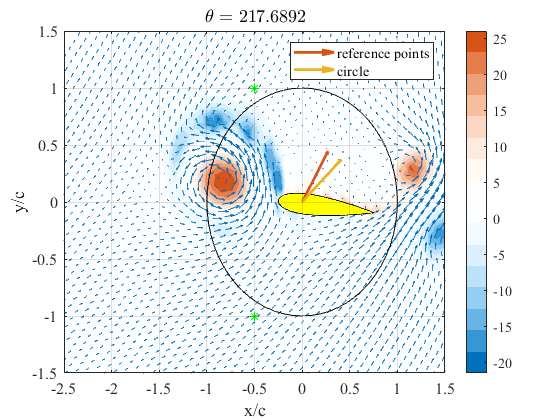

k = 42

ans = 38.4466

ans = -24.4414

f =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '241New.png'

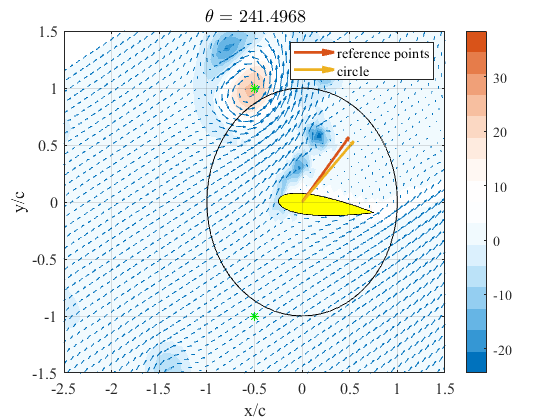

k = 47

ans = 38.2275

ans = -24.0706

f =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


filename = '271New.png'

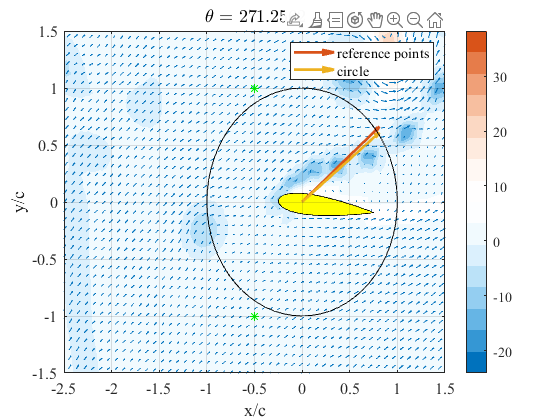

klist = [1 16 22 25 27 32 38 42 47];
for i = 1:length(klist)
    k = klist(i)
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    u5 = Us(k).u3+norm(bv);
    v5 = Us(k).v3;
    XY = [X(:) Y(:)];
    XYRy2 = XY*Ry2;
    res = subs(XYRy2,t,-alpha);
    res = double(res);
    Xrot3 = reshape(res(:,1), size(X,1), []);
    Yrot3 = reshape(res(:,2), size(Y,1), []);
    Yrot4 = Yrot3-2.042;
    [curlz,cav] = curl(Xrot3,Yrot4,u5,v5);
    max(max(curlz))
    min(min(curlz))
    [Cin,Ca] = Circle2([0;0],1,Xrot3,Yrot4);
    [Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
    foiltest2 = plot_foil(theta(k),1);
    XYRy2 = Ry2*foiltest2';
    res = subs(XYRy2,t,alpha);
    foiltest2(:,:) = res';
    f = figure
    pcolor(Xrot3,Yrot4,curlz)
    shading interp
    % map = [1 0 0;1 1 1;0 0 1]
    vec = [100;50;0];
    raw = [0 0.4470 0.7410; 1 1 1;0.8500 0.3250 0.0980];
    N = 16;
    map = interp1(vec,raw,linspace(100,0,N),'pchip');
    map = abs(map);
    colormap(map)
    colorbar
    hold on
    quiver(Xrot3,Yrot4,u5,v5)
    xlim([-2.5 1.5])
    ylim([-1.5 1.5])
    fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
    quiver(0,0,(mean(u5(logical(Pin))))/Uinf*Uinf,(mean(v5(logical(Pin))))/Uinf*Uinf,'LineWidth',2)
    quiver(0,0,(mean(u5(logical(Cin))))/Uinf*Uinf,(mean(v5(logical(Cin))))/Uinf*Uinf,'LineWidth',2)
    plot(Pa(1,:),Pa(2,:),'g*')
    plot(Ca(:,1),Ca(:,2),'k')
    grid on
    set(gca,'layer','top','FontName','Times','FontSize',12)
    xticks(-2.5:0.5:1.5)
    yticks(-1.5:0.5:1.5)
    xlabel('x/c')
    ylabel('y/c')
    title(strcat('$\theta$',sprintf(' = %.4f',theta(k))),'Interpreter','latex')
    hold off
    set(gcf,'Visible','on','Color','w')
    legend('','','','reference points','circle')
    filename = sprintf('%.0fNew.png',abs(theta(k)))
    saveas(f,filename)
end